## **Dynamics of First Order Systems**

### **Learning Objectives:**

**1) Be able to explain the key parameters of first and second order systems by articulating how changes in these parameters affect their dynamic behavior**

**2) Be able to utilize simulation to assess dynamic behavior of first and second order systems under different forcing functions**

In engineering, phenomenon can generally be described through first and second order differential equations. Through the use of transfer functions, we can easily understand the dynamics of such systems under different forcing functions. 

*First Order Transfer Function*

For applications towards chemical engineering, we have seen the derivation for the liquid level tank to be a first order system, which is given as the following: 

The linear first order differential equation is written in the following standard form: $a_0\frac{dy}{dt} + a_1y = bu(t)$, where $y(t)$ is the output function, $u(t)$ is the input function.

One can rearrange the equation into the following form: $\tau\frac{dy}{dt} + y = Ku(t)$, where $\tau = \frac{a_0}{a_1}$ and $K = \frac{b}{a_1}$.

By taking the laplace transform of Eq (2), we obtain: $y(s) = \frac{K}{\tau s + 1}u(s)$, where $g(s) = \frac{K}{\tau s + 1}$ is known as the transfer function. 

Four forcing functions are provided in the drop down menu below: Unit Step, Impulse, Sine, and Pulse (5 

second pulse of amplitude 1)

**Question 1: For the unit step change, what happens to the final steady state value as K you change K?**

**Question 2: For the unit step change, how does changing tau affect the dynamic response? **

**Question 3: For the pulse response, when does the system output increase? When does the system output decrease? **

**Question 4: For the pulse response, under what parameters of K and/or tau does the system reach a steady state value? **

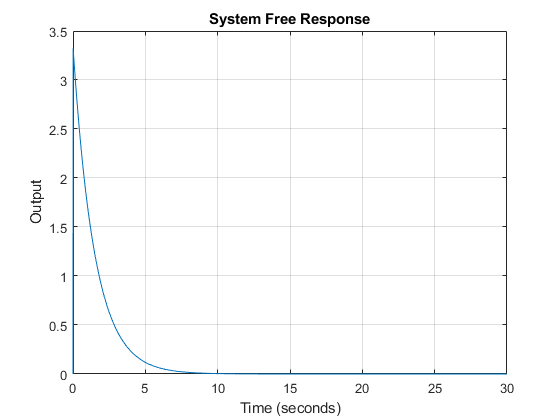


k = 5;
Tau=1.5;
EndTime = 30;
[A B C D] = tf2ss([k],[Tau 1]); x0 = 0;
sys = ss(A,B,C,D);
t = 0:0.01:EndTime; 
[~,z] = size(t);
u = zeros(1,z); u(1)=100;;
[y] = lsim(sys,u,t,x0);
figure(1);
plot(t,y);
grid
xlabel('Time (seconds)')
ylabel('Output')
title('System Free Response')

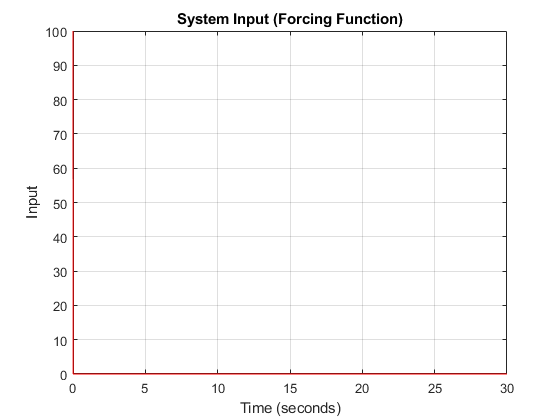

figure(2);
plot(t,u,'r');
grid
xlabel('Time (seconds)')
ylabel('Input')
title('System Input (Forcing Function)')

## **Dynamics of Second Order Systems**

In engineering, phenomenon can generally be described through second order differential equations. Through the use of transfer functions, we can easily understand the dynamics of such systems under different forcing functions. 

*Second Order Transfer Function*

The linear second order differential equation with constant coefficients is written in the following standard form: $a_2\frac{d^2y}{dt^2}+a_1\frac{dy}{dt} + a_0y = bu(t)$, where $y(t)$ is the output function, $u(t)$ is the input function.

One can rearrange the equation into the following form: $\tau^2\frac{d^2y}{dt^2}+2\zeta\tau\frac{dy}{dt} + y = Ku(t)$, where $\tau^2 = \frac{a_2}{a_0}$, $2\zeta\tau = \frac{a_1}{a_0}$ and $K = \frac{b}{a_0}$.

By taking the laplace transform of Eq (2), we obtain: $y(s) = \frac{K}{\tau^2 s^2 + 2\zeta \tau s + 1}u(s)$, where $g(s) =  \frac{K}{\tau^2 s^2 + 2\zeta \tau s + 1}$ is known as the transfer function. 

For applications towards chemical engineering, we have seen the derivation for two tanks systems in series to be a second order system, which is given by: $\tau_1\tau_2\frac{d^2h'}{dt^2} + (\tau_1+\tau_2)\frac{dy}{dt} + h' = K_1K_2F'$, where $\tau_1$ and $\tau_2$ are the time constants for the first and second tanks and $K_1$ and $K_2$ are the process gains for the first and second tanks, respectively. 

For Questions 1-3, use a step response.

**Question 1: First, adjust K while keeping Tau and Zeta constant. What happens when you adjust K?**

**Question 2: Second, keep k and Zeta constant. What happens when you vary Tau? **

**Question 3: Third, keep k and Tau constant. What happens when you vary Zeta? **


k = 2.8;
Tau = 3.1;
Zeta = 2.5;
[A B C D] = tf2ss([k],[Tau^2 2*Zeta*Tau 2]); x0 = [0;0];
sys = ss(A,B,C,D);
EndTime = 70;
t = 0:0.1:EndTime;
[~,z] = size(t);
u = ones(1,z)*1;
[y] = lsim(sys,u,t,x0);
figure(1);
plot(t,y);
grid
xlabel('Time (seconds)')
ylabel('Output')
title('System Free Response')